# PID Tuning

**Objective:** **Tune a discrete PID controller and test the performance with a series of setpoint changes over 10 min in the sequence from   initially, **$50^\circ\text{C}$** at 10 sec, and **$40^\circ\text{C}$** at 300 sec. Modify the tuning parameters to achieve a low Integral Absolute Error between the measured temperature and the setpoint.**

## **TCLab PID Control Simulator**

A simulator is a useful tool to help evaluate changes in tuning before testing on a physical system. Use the PID simulator to find acceptable control performance that minimizes the integral absolute error between the setpoint and measured temperature.

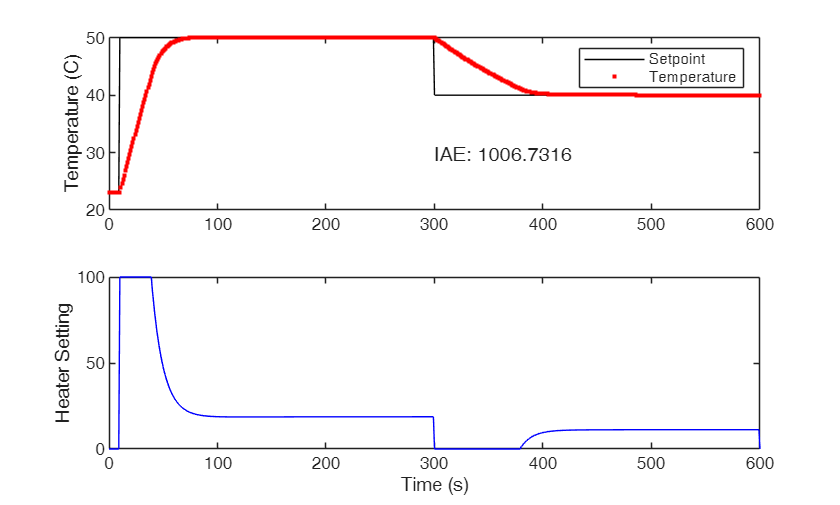

clear;clc;
Kc = 25;
tauI = 65;
tauD = 4;
pidPlot(Kc, tauI, tauD)

## TCLab PID Control Test

viewSolution(true)

Using the PID Parameters from the simulation, implement PID control in the TCLab with a series of setpoint changes over 10 min in the sequence from $23^\circ\text{C}$ initially, $50^\circ\text{C}$ at 10 sec, and $40^\circ\text{C}$ at 300 sec.

Kc = 22

Kc =     22


tauI = 60

tauI =     60


tauD = 4

tauD =      4


params = [Kc tauI tauD];

% create arrays for loop
n = 600;
tm_ = linspace(0, n, n+1);
T1_ = zeros(n, 1);
Q1_ = zeros(n, 1);
SP1_ = ones(n, 1) * 23.0;
SP1_(10:end) = 60.0;
SP1_(300:end) = 40.0;
ierr = 0;

% loop through control with tclab
tclab;

  arduino with properties:

                  Port: 'COM8'
                 Board: 'Uno'
         AvailablePins: {'D2-D13', 'A0-A5'}
  AvailableDigitalPins: {'D2-D13', 'A0-A5'}
      AvailablePWMPins: {'D3', 'D5-D6', 'D9-D11'}
   AvailableAnalogPins: {'A0-A5'}
    AvailableI2CBusIDs: [0]
             Libraries: {'I2C', 'SPI', 'Servo'}
Show all properties



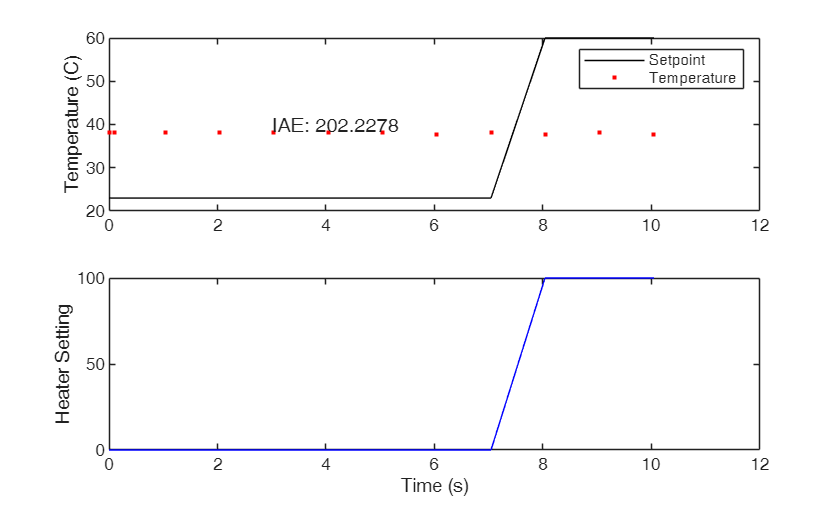

T1_(1) = T1C();
tic
figure
hold on
for i = 2:n-1
    T1_(i) = T1C();
    tm_(i) = toc;
    [Q1_(i), P, ierr, D] = pidController(params, SP1_(i), T1_(i), T1_(i-1), ierr, tm_(i) - tm_(i-1));
    h1(Q1_(i));

    % plot
    subplot(2,1,1)
    plot(tm_(1:i), SP1_(1:i), 'k-', 'DisplayName','Setpoint')
    hold on
    plot(tm_(1:i), T1_(1:i), 'r.', 'DisplayName','Temperature')
    hold off
    text(3, 40, 'IAE: '+string(sum(abs(SP1_(1:i)-T1_(1:i)))))
    legend
    ylabel('Temperature (C)')
    subplot(2,1,2)
    plot(tm_(1:i), Q1_(1:i), 'b-')
    ylabel('Heater Setting')
    xlabel('Time (s)')
    
    % wait
    pause(1-mod(toc, 1))
end

function [op, I, ierr, D] = pidController(params, sp, pv, pv_last, ierr, dt)
    % PID controller. ubias of 0 and output range of 0 to 100 assumed
    % INPUTS
    % params (array): controller constants for PID controller
    %     kC: controller gain
    %     TauI: integral time constant
    %     TauD: derivative time constant
    % sp: setpoint of controller
    % pv: process value
    % pv_last: previous process value
    % ierr: integral of error
    % dt: time step between measurements
    % OUTPUTS
    % op: controlled value setting
    % ierr: new integral of error after timestep

    % unpack params
    kC = params(1);
    tauI = params(2);
    tauD = params(3);

    % calculate PID equation
    e = sp - pv;
    ierr = ierr + e*dt;
    dedt = (pv - pv_last)/dt;

    P = kC * e;
    I = kC/tauI * ierr;
    D = -tauD * kC * dedt;
    op = P + I + D;

    % anti-reset windup
    % Anti-reset windup
    if op > 100  % check upper limit
        op = 100;
        ierr = ierr - e * dt; % anti-reset windup
    elseif op < 0  % check upper limit
        op = 0;
        ierr = ierr - e * dt; % anti-reset windup
    end
end


## Functions (Add any needed functions below)

function dydt = fopdt(~, y, u)
    dydt = (-(y-25.0) + 1.333 * u)/180.0;
end

function pidPlot(kC, tauI, tauD)
    n = 601;  % number of measurements
    op_hi = 100;
    op_lo = 0;
    
    tm_ = linspace(0, n-1, n);
    P_ = zeros(1, n);
    I_ = zeros(1, n);
    D_ = zeros(1, n);
    e_ = zeros(1, n);
    OP_ = zeros(1, n);
    PV_ = ones(1, n) * 23.0;
    SP_ = ones(1, n) * 23.0;
    SP_(11:end) = 50.0;
    SP_(301:end) = 40;
    ie = 0.0;
    dt = tm_(2) - tm_(1);
    pv0 = 23.0;
    
    % simulate PID
    for i=1:n-1
        e_(i) = SP_(i) - PV_(i);
        ie = ie + e_(i) * dt;
        if i> 2
            dedt = (PV_(i) - PV_(i-1))/dt;
        else
            dedt = 0;
        end      
        
        P_(i) = kC * e_(i);
        I_(i) = kC/tauI * ie;
        D_(i) = -kC * tauD * dedt;
        
        op = P_(i) + I_(i) + D_(i);
        OP_(i) = min(max(op,op_lo),op_hi);
        if (OP_(i) == op_lo ) || (OP_(i) == op_hi)
            ie = ie-e_(i) * dt;
        end
        [~,y] = ode45(@(t,y) fopdt(t,y,OP_(i)),[tm_(i) tm_(i) + dt],pv0);
        pv0 = y(end);
        PV_(i+1) = pv0;
        
         
    end
    
    figure()
    subplot(2,1,1)
    plot(tm_, SP_, 'k-', 'DisplayName','Setpoint')
    hold on
    plot(tm_, PV_, 'r.', 'DisplayName','Temperature')
    text(300, 30, 'IAE: '+string(sum(abs(SP_-PV_))))
    legend
    ylabel('Temperature (C)')
    subplot(2,1,2)
    plot(tm_, OP_, 'b-')
    ylabel('Heater Setting')
    xlabel('Time (s)')
end

## Solution

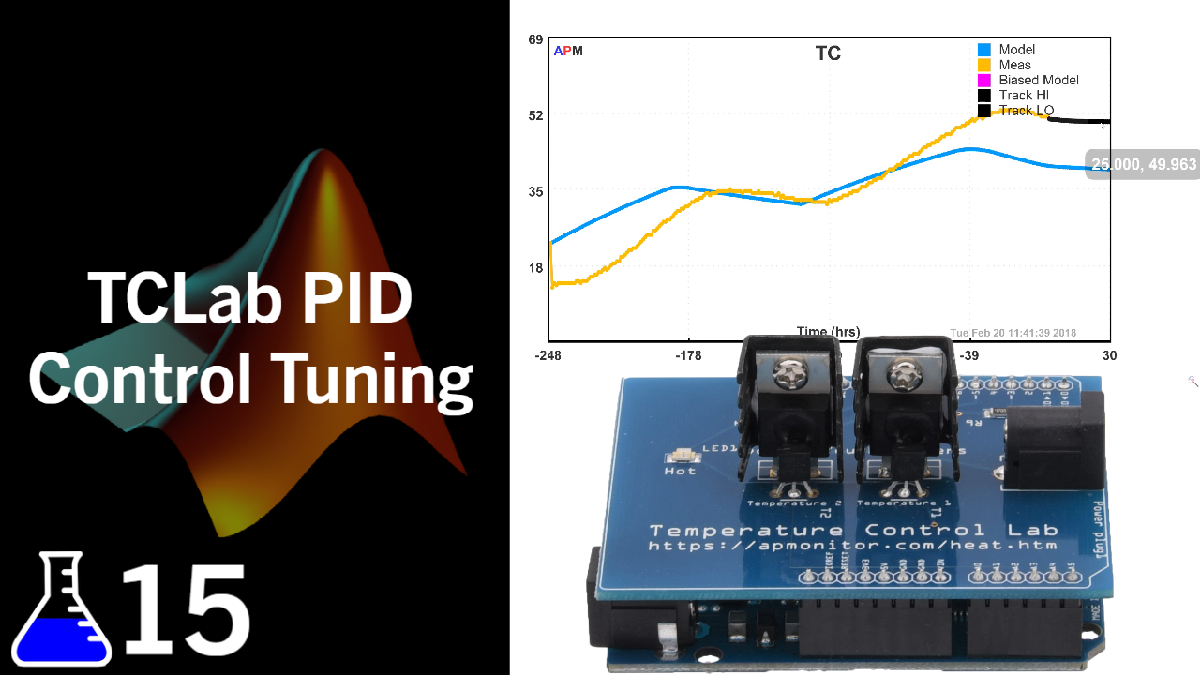

### [View Solution Video](https://youtu.be/iVBR2yU6wyo)

function viewSolution(view)
if view
	disp("Kc = 15" + newline + ...
	     "tauI = 60" + newline + ...
	     "tauD = 4" + newline + ...
	     "params = [Kc tauI tauD];" + newline + ...
	     "" + newline + ...
	     "% create arrays for loop" + newline + ...
	     "n = 600;" + newline + ...
	     "tm_ = linspace(0, n, n+1);" + newline + ...
	     "T1_ = zeros(n, 1);" + newline + ...
	     "Q1_ = zeros(n, 1);" + newline + ...
	     "SP1_ = ones(n, 1) * 23.0;" + newline + ...
	     "SP1_(10:end) = 60.0;" + newline + ...
	     "ierr = 0;" + newline + ...
	     "" + newline + ...
	     "% loop through control with tclab" + newline + ...
	     "lab = tclab;" + newline + ...
	     "T1_(1) = lab.T1;" + newline + ...
	     "tic" + newline + ...
	     "figure" + newline + ...
	     "hold on" + newline + ...
	     "for i = 2:n-1" + newline + ...
	     "    T1_(i) = lab.T1;" + newline + ...
	     "    tm_(i) = toc;" + newline + ...
	     "    [Q1_(i), ierr] = pidController(params, SP1_(i), T1_(i), T1_(i-1), ierr, tm_(i) - tm_(i-1));" + newline + ...
	     "    lab.Q1(Q1_(i));" + newline + ...
	     "    " + newline + ...
	     "    % plot" + newline + ...
	     "    subplot(2,1,1)" + newline + ...
	     "    plot(tm_(1:i), SP1_(1:i), 'k-', 'DisplayName','Setpoint')" + newline + ...
	     "    hold on" + newline + ...
	     "    plot(tm_(1:i), T1_(1:i), 'r.', 'DisplayName','Temperature')" + newline + ...
	     "    hold off" + newline + ...
	     "    text(3, 40, 'IAE: '+string(sum(abs(SP1_(1:i)-T1_(1:i)))))" + newline + ...
	     "    legend" + newline + ...
	     "    ylabel('Temperature (C)')" + newline + ...
	     "    subplot(2,1,2)" + newline + ...
	     "    plot(tm_(1:i), Q1_(1:i), 'b-')" + newline + ...
	     "    ylabel('Heater Setting')" + newline + ...
	     "    xlabel('Time (s)')" + newline + ...
	     "    " + newline + ...
	     "    % wait" + newline + ...
	     "    pause(mod((1-toc), 1))" + newline + ...
	     "end" + newline + ...
	     "" + newline + ...
	     "--- snip ---" + newline + ...
	     "" + newline + ...
	     "function [op, ierr] = pidController(params, sp, pv, pv_last, ierr, dt)" + newline + ...
	     "    % PID controller. ubias of 0 and output range of 0 to 100 assumed" + newline + ...
	     "    % INPUTS" + newline + ...
	     "    % params (array): controller constants for PID controller" + newline + ...
	     "    %     kC: controller gain" + newline + ...
	     "    %     TauI: integral time constant" + newline + ...
	     "    %     TauD: derivative time constant" + newline + ...
	     "    % sp: setpoint of controller" + newline + ...
	     "    % pv: process value" + newline + ...
	     "    % pv_last: previous process value" + newline + ...
	     "    % ierr: integral of error" + newline + ...
	     "    % dt: time step between measurements" + newline + ...
	     "    % OUTPUTS" + newline + ...
	     "    % op: controlled value setting" + newline + ...
	     "    % ierr: new integral of error after timestep" + newline + ...
	     "    " + newline + ...
	     "    % unpack params" + newline + ...
	     "    kC = params(1);" + newline + ...
	     "    tauI = params(2);" + newline + ...
	     "    tauD = params(3);" + newline + ...
	     "    " + newline + ...
	     "    % calculate PID equation" + newline + ...
	     "    e = sp - pv;" + newline + ...
	     "    ierr = ierr + e*dt;" + newline + ...
	     "    dedt = (pv - pv_last)/dt;" + newline + ...
	     "    " + newline + ...
	     "    P = kC * e;" + newline + ...
	     "    I = kC/tauI * ierr;" + newline + ...
	     "    D = -tauD * kC * dedt;" + newline + ...
	     "    op = P + I + D;" + newline + ...
	     "    " + newline + ...
	     "    % anti-reset windup" + newline + ...
	     "    % Anti-reset windup" + newline + ...
	     "    if op > 100  % check upper limit" + newline + ...
	     "        op = 100;" + newline + ...
	     "        ierr = ierr - e * dt; % anti-reset windup" + newline + ...
	     "    elseif op < 0  % check upper limit" + newline + ...
	     "        op = 0;" + newline + ...
	     "        ierr = ierr - e * dt; % anti-reset windup" + newline + ...
	     "    end" + newline + ...
	 "end")
end
end
